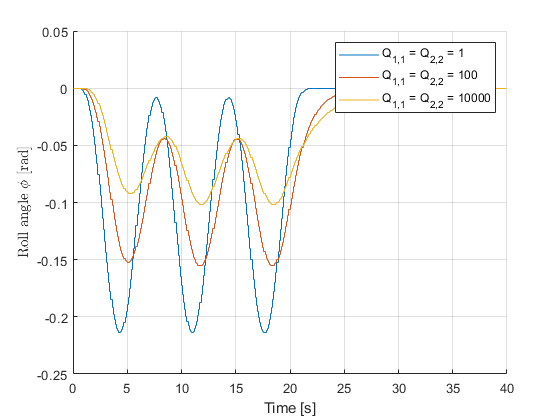

clear all
close all

steps = 400;
t_time = linspace(0,40,steps+1);

load("MPC_output_v_2\Output_MPC_States_v_2_Q_01_01_1_1_R_1.mat")
x_Q_01 = x;

load("MPC_output_v_2\Output_MPC_States_v_2_Q_1_R_1.mat")
x_Q_1 = x;

load("MPC_output_v_2\Output_MPC_States_v_2_Q_10_10_1_1_R_1.mat")
x_Q_10 = x;

load("MPC_output_v_2\Output_MPC_States_v_2_Q_100_100_1_1_R_1.mat")
x_Q_100 = x;

load("MPC_output_v_2\Output_MPC_States_v_2_Q_1000_1000_1_1_R_1.mat")
x_Q_1000 = x;

load("MPC_output_v_2\Output_MPC_States_v_2_Q_10000_10000_1_1_R_1.mat")
x_Q_10000 = x;


figure(1)
hold on
grid on
% stairs(t_time,x_Q_01(1,:))
stairs(t_time,x_Q_1(1,:))
% stairs(t_time,x_Q_10(1,:))
stairs(t_time,x_Q_100(1,:))
% stairs(t_time,x_Q_1000(1,:))
stairs(t_time,x_Q_10000(1,:))
legend('Q_{1,1} = Q_{2,2} = 1','Q_{1,1} = Q_{2,2} = 100','Q_{1,1} = Q_{2,2} = 10000')
ylabel('Roll angle $\phi$ [rad]','Interpreter',"latex")
xlabel("Time [s]")
hold off